# Estimation of blood pressure parameters from ECG and PPG signals

## Dataset

Data were used from a Cold Pressor study of healthy volunteers at the Biomedical Engineering Institute (Kaunas, Lithuania), with approval by the Kaunas Region Biomedical Research Ethics Committee (No. BE-2-24). The total number of participants was 35. 

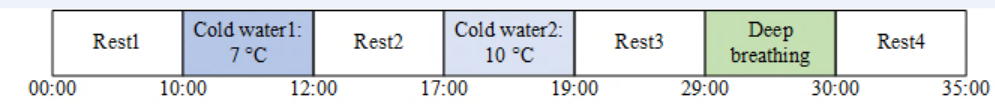

Signals: 1) reference blood pressure wave - CNAP Monitor (CNSystems, Graz, Austria), sampling rate 100Hz; 2) ECG and PPG - Nautilus (Biomedical engineering institute, Kaunas, Lithuania), sampling rate for ECG - 2000Hz, and 1000Hz for PPG. ECG array contains 3 leads (Lead 1, Lead II, Lead III) in 3xn matrix. PPG array contains 2 channels (IR- infrared and R- red LEDs) in 2xm matrix. 

## Load and visualise the signals

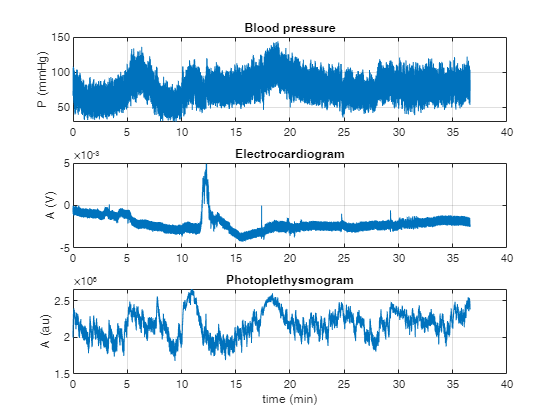

clear all
close all

fname='Painless02.mat';
load(fname);


figure
t_bp=(0:length(bp)-1)*1/f_bp;
subplot(3,1,1),plot(t_bp/60, bp),grid
title('Blood pressure'), ylabel('P (mmHg)')


t_ecg=(0:length(ecg(1,:))-1)*1/f_ecg;
subplot(3,1,2),plot(t_ecg/60, ecg(1,:)),grid
title('Electrocardiogram'), ylabel('A (V)')

t_ppg=(0:length(ppg(1,:))-1)*1/f_ppg;
subplot(3,1,3),plot(t_ppg/60, ppg(1,:)),grid
title('Photoplethysmogram'), ylabel('A (au)'), xlabel('time (min)')

## Preprocessing

1) Extract systolic (SBP), dyastolic (DBP) and mean blood pressures (MBP)

2) Equalize sampling frequencies of the signals to 500Hz. 

3) Low- and highpass filter ECG and PPG signals: eg., f_co_hp=0.5Hz,  f_co_lp= 17Hz 

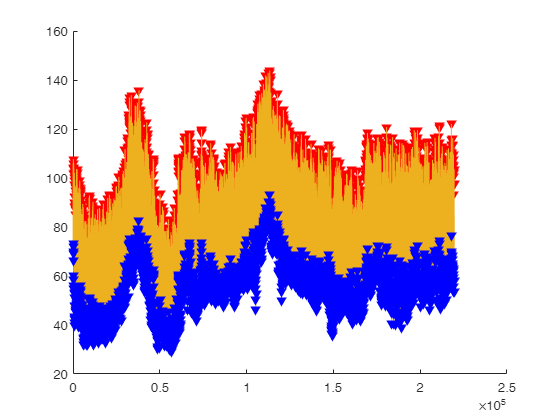

% Extract systolic, dyastolic and mean blood pressures
figure
hold on
% find SBP
[~,locs_SBP] = findpeaks(bp,'MinPeakDistance',50);
plot(bp),grid
plot(locs_SBP,bp(locs_SBP),'rv','MarkerFaceColor','r')

% find DBP
[~,locs_DBP] = findpeaks(-bp,'MinPeakDistance',50);
plot(bp),grid
plot(locs_DBP,bp(locs_DBP),'bv','MarkerFaceColor','b')

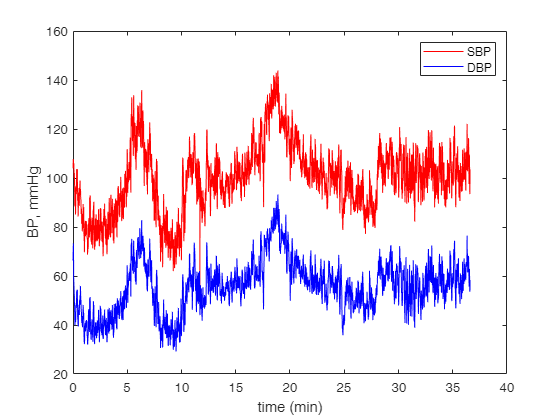


% find MBP
...

SBP= bp(locs_SBP);
DBP= bp(locs_DBP);
%MBP - ? % Home work 
figure
t_SBP=locs_SBP*1/100;
plot(t_SBP/60,SBP,'r')
xlabel('beat No')
hold on
t_DBP=locs_DBP*1/100;
plot(t_DBP/60, DBP,'b')
xlabel('time (min)'), ylabel('BP, mmHg')
legend('SBP', 'DBP')
hold off

return

% Decimation y = decimate(x,r) 




## Feature extraction

Extract the following features: 

1) Pulse Arrival Time (PAT)

2) Pulse intensity ratio (PIR)

3) Heart rate (HR)  

% Extract PAT


% Extract PIR

% Extract HR

% (until 2021.11.26)

## Regression

### Train a regression model

Start with [linear regression](https://se.mathworks.com/help/stats/what-is-linear-regression.html). Use phases "Rest1" and "ColdWater1" for **training**.

Terms:

    Predictor variable X (matrix)

    Response variable y (vector)

Use fitlm for training the model [`mdl = fitlm(X,y)`](https://se.mathworks.com/help/stats/fitlm.html#d123e354383)

% First regress only PAT against SBP
...


### Evaluate the regression model 

Use the object function [`anova`](https://se.mathworks.com/help/stats/linearmodel.anova.html). This function returns analysis of variance (ANOVA) statistics of the model.

%
...

### **Predict responses to new data**

Predict responses to the test data set by using the fitted model `newMdl2` and the object function [`predict`](https://se.mathworks.com/help/stats/linearmodel.predict.html) 

Use phases "Rest2" and "ColdWater2" for **testing**. 

%
...

## Classification

### Train a classification model 

Use phases "Rest1" and "ColdWater1" for **training the model for** segmentation of the signal into 3 classes: a) SBP 

% ...

### Validate the classification model

...

%...


### Test and evaluate the classification model

...

%....
